# Using Dynamically Loaded Filters in MatMWB

## Installing Dynamically Loaded Filters

HDF5 can use various filters to compress data when writing datasets. GZIP is the default filter, and it can be read with any HDF5 installation without any setup, but many users find that other filters, such as Zstd, offer better performance. If you want to read an HDF5 Dataset that was compressed using another filter in MATLAB, such as Zstd, you will need to configure MATLAB to read using dynamically loaded filters. 

The easiest way we have found to set up dynamically loaded filters is to use the Python package [hdf5plugin](https://github.com/silx-kit/hdf5plugin). This library has a sophisticated installation process that compiles several of the most popular dynamically loaded filters and works across popular operating systems. Installing this Python package is a trick that allows us to offload the tricky parts of installing dynamically loaded filters in MATLAB.

### Linux or Mac

1. In your Terminal window, install hdf5plugin:

`pip install hdf5plugin`

2. In that same Terminal window, set the environment variable `HDF5_PLUGIN_PATH`:

`export HDF5_PLUGIN_PATH=$(python -c "import hdf5plugin; print(hdf5plugin.PLUGINS_PATH)");`

3. From that same Terminal window, launch MATLAB:

`/Applications/MATLAB_R2021b.app/bin/matlab`

The path above is an example of a common location for OSX. The exact path of MATLAB may vary on your computer.

### Windows

1. Install `hdf5plugin` in the Command Prompt:

`pip install hdf5plugin`

2. Determine the path of the plugin installation. In the Command Prompt, run:

`python -c "import hdf5plugin; print(hdf5plugin.PLUGINS_PATH)`

2. Set the environment variable `HDF5_PLUGIN_PATH `to point to the local installation of the plugins (from `hdf5plugin.PLUGINS_PATH`) through *System Properties > Advanced > Environment Variables:*

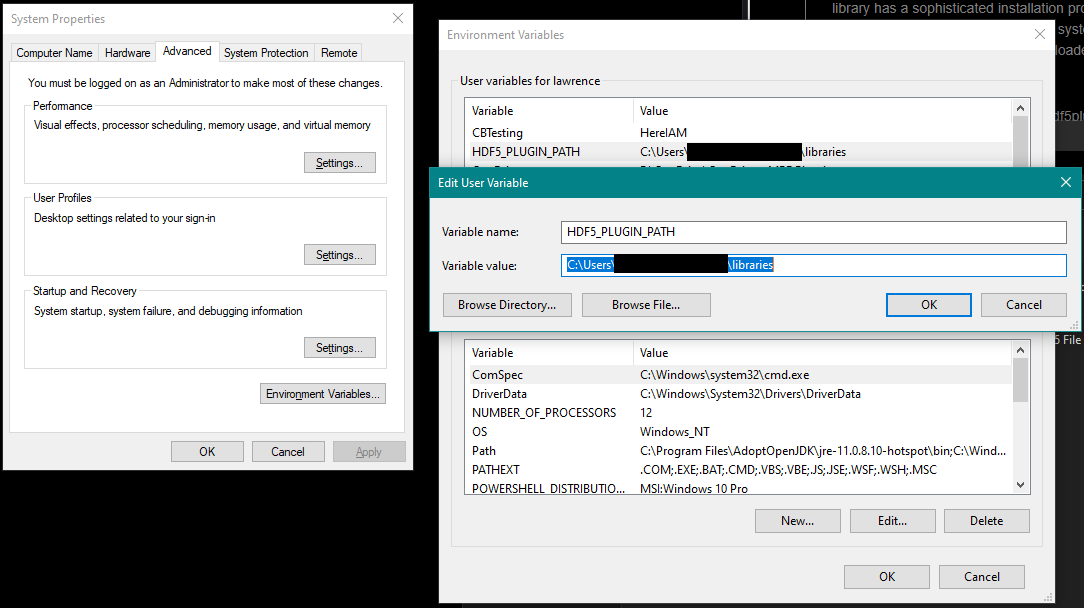

3. Restart MATLAB.

That's it! Now you can read datasets that use the following filters:

- Bitshuffle

- Blosc

- FciDecomp

- LZ4

- Zfp

- Zstd

The beauty of HDF5 is that it handles the rest under the hood. When you read a dataset that uses any of these filters, HDF5 will identify the correct decompression algorithm and decompress the data on-the-fly as you access it from the dataset.

For more information about installing filter plugins, see the [MATLAB documentation](https://www.mathworks.com/help/matlab/import_export/read-and-write-hdf5-datasets-using-dynamically-loaded-filters.html).

## Writing with Dynamically Loaded Filters

To write with dynamically loaded filters, first follow the installation steps above. **This feature requires MATLAB version ≥ 2022a.**

`DataPipe` objects can be used to write using Dynamically loaded filters. This tutorial will be using the [Zstd dynamic filter](https://github.com/aparamon/HDF5Plugin-Zstandard) as an example.

The `DynamicFilter` property takes in an enumerated type `Filter` which is a hard-coded list of all listed [registered filter plugins](https://portal.hdfgroup.org/display/support/Registered+Filter+Plugins) in HDF5.

import matnwb.types.untyped.datapipe.properties.DynamicFilter
import matnwb.types.untyped.datapipe.dynamic.Filter
import matnwb.types.untyped.datapipe.properties.Shuffle

zstdProperty = DynamicFilter(Filter.ZStandard);

### Parameters

Some filter plugins allow for setting special configuration parameters to modify the filter's behavior. The `DynamicFilter` property type contains a modifiable `parameters `field which can be used to set your parameters. This is equivalent to setting the `cd_values` argument in HDF5. In the case of the [Zstandard HDF5 plugin](https://github.com/aparamon/HDF5Plugin-Zstandard), the first (and only) array argument value indicates the compression level.

zstdProperty.parameters = 4; % compression level.

### Multiple Filters

You can use multiple dynamic filters by concatenating multiple DynamicFilter properties together. They will be applied in order of the inserted array.

ShuffleProperty = Shuffle();
dynamicProperties = [ShuffleProperty zstdProperty];

### Writing

The `DataPipe` class takes in a keyword argument called f`ilters` which is an array of `DynamicFilter` objects. Supplying a `'filters'` argument will deactivate the default GZIP compression.

% We're already compressing using zstd so we should disable
% compressionLevel (gzip).
dataPipe = matnwb.types.untyped.DataPipe('data', rand(1, 10000), 'filters', dynamicProperties);

timeseries = matnwb.types.core.TimeSeries('data', dataPipe, 'data_unit', 'data-unit');

nwbFile = NwbFile();
nwbFile.acquisition.set('ts', timeseries);

nwbExport(nwbFile, 'test.nwb');


The data is now compressed using Zstandard compression using a compression level of 4 and Shuffled